% MATLAB HW2_1
% Signals and Systems, Spring, 2023
%
% Original Source: LIST, Seoul National University
% http://list.snu.ac.kr
% Editor & Assignment Evaluator: Dongju Mun @ ICL, Seoul National University
% dongju1126@snu.ac.kr

## Introduction

% In this homework, you will implement the 2D convolution operation
% You can implement 2D convolution operation using 4 nested for loops
% when the filter is 2D
% Alternatively, if the 2D filter is separable, you can perform
% 2D convolution using 1D filter twice
% As you expected, the latter method is less computational expensive

## Problem1. 2D convolution using 2D filter

% reset workspace
clear;

% load sample image
load cameraman;

% load gaussian filter
% note that gaussian filter is symmetric
w = gausswin(9); % type help gausswin to understand this command

'gausswin'에는 Signal Processing Toolbox이(가) 필요합니다.

gauss_filter = w*w'; % 2D Gaussian filter

% clock start
tic

%%%%%%%%%%%% implement conv_2d_filter.m %%%%%%%%%%%%%%%%
result_im = conv_2d_filter(cameraman,gauss_filter);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% clock end
disp(['problem 1 run time: ',num2str(toc),' seconds']);

% 2D convolution result using MATLAB function
conv2_result = conv2(cameraman,gauss_filter,'same');

% compare the results
figure;
subplot(1,3,1); imshow(cameraman,[0 256]); title('Original image');
subplot(1,3,2); imshow(result_im,[0 4000]); title('Your result');
subplot(1,3,3); imshow(conv2_result,[0 4000]); title('MATLAB conv2 result');

## Example

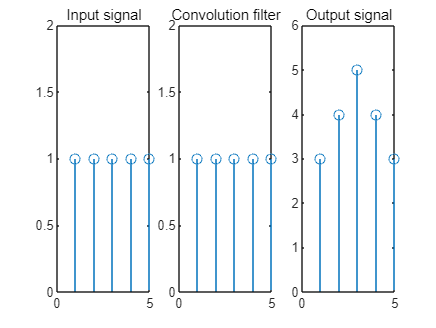

% In this part, we will introduce the method that perform 1D convolution
% (for 1D filter) without any for loops
% Read carefully below code and understand it
% you might need this code for solving Problem 2
%
% To understand this part, it would be helpful to understand following MATALB functions:
% repmat, reshape
% you can easily find the usage of these commands in the internet

% reset workspace
clear;

% origianl signal
x = ones(5,1);

% convolution filter
h = ones(5,1);

% zero-pad the original signal
x_pad = zeros(size(x,1)+size(h,1)-1,1);
x_pad((size(h,1)-1)/2+1:(size(h,1)-1)/2+size(x,1)) = x;

% flip the convolution filter
h = h(end:-1:1);

% make convolution matrix
H_row = [h', zeros(1,size(x_pad,1)-size(h,1)+1)];
H_rep = repmat(H_row,1,size(x_pad,1));
H = reshape(H_rep,size(x_pad,1),[]);
H = H(:,1:size(x,1));

% perform 1D convolution
y = x_pad' * H;

% plot the convolution result
figure;
subplot(1,3,1); stem(x); title('Input signal'); ylim([0 2]);
subplot(1,3,2); stem(h); title('Convolution filter'); ylim([0 2]);
subplot(1,3,3); stem(y); title('Output signal'); ylim([0 6]);


% Note that y has same size of x
% (Because x is zero-padded)

## Problem 2. 2D convolution using 1D filter twice

% reset workspace
clear;

% load sample image
load cameraman;

% load gaussian filter
w = gausswin(9);
filter_x = w; % size = (9,1)
filter_y = w'; % size = (1,9)
gauss_filter = filter_x * filter_y; % size = (9,9)

% Here, Gaussian filter of size (9,9) can be separable by two 1D filter
% which are filter_x (size = (9,1)) and filter_y (size = (1,9))
% Instead of perform 2D convolution using 2D filter as done in Problem 1,
% we can get a same result by performing 2D convolution using 1D filter twice
% reference: http://www.songho.ca/dsp/convolution/convolution.html#convolution_2d
%
% In this problem, we will implement this operation without using any for loops
% you may be better to refer the above Example section code for implementation

% clock start
tic

%%%%%%%%%%%% implement conv_1d_filter_x.m %%%%%%%%%%%%%%
result_im_x = conv_1d_filter_x(cameraman,filter_x);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%% implement conv_1d_filter_y.m %%%%%%%%%%%%%%
% consider to use conv_1d_filter_x function above
% with image rotation and filter transpose
% this MATLAB function may be useful: rot90
result_im = conv_1d_filter_y(result_im_x,filter_y);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% clock end
disp(['problem 2 run time: ',num2str(toc),' seconds']);

% 2D convolution result using MATLAB function
conv2_result = conv2(cameraman,gauss_filter,'same');

% compare the results
figure;
subplot(1,3,1); imshow(cameraman,[0 256]); title('Original image');
subplot(1,3,2); imshow(result_im,[0 4000]); title('Your result');
subplot(1,3,3); imshow(conv2_result,[0 4000]); title('MATLAB conv2 result');

% additioanl question (not graded):
% which run time is shorter? (problem 1 and problem 2)